#### `N foot position: `$r_{f,i}$

clear all; clc; close all;
N = 2;
foot_W = 0.05;
foot_H = 0.1625; % 0.15
foot_stride_y = 0.05;
foot_stride_x = 0.1625; % 0.15
is_left = false;
swingHeight = 0.1;

msup = 3; %5
mswg = 3; %5
mpend = 54;
mfeet = 6;
mtotal = 60;
g = 9.807; 
delta_z_vrp = 0.8; %0.68
omega = sqrt(g/delta_z_vrp);
% z_robot = 0.78;
t_step = 0.65; %0.8
t_sample = 0.001; %0.01
tDS = 0.1;
alpha = 0.5;
tSS = t_step - tDS;
t=0:t_sample:t_step*(N+2) - t_sample;

traj_ds = struct('index', {}, 'xi_ds', {}, 'state', {});
traj_ss = struct('index', {}, 'xi_ss', {}, 'state', {});


for i=1:N+3
    if i == 1
        r_f_r(i,1) = 0;
        r_f_l(i,1) = 0;
    elseif i == N+3
        r_f_l(i, 1) = (foot_H + foot_stride_x)*(i-2);
        r_f_r(i,1) = (foot_H + foot_stride_x)*(i-2);
    elseif mod(i,2) == 0
        r_f_l(i,1) = (foot_H + foot_stride_x)*(i-1);
        r_f_r(i,1) = r_f_r(i-1,1);  
    else
        r_f_r(i,1) = (foot_H + foot_stride_x)*(i-1);
        r_f_l(i,1) = r_f_l(i-1,1);
    end
    r_f_l(i,2:3) = [(foot_W + foot_stride_y) 0];
    r_f_r(i,2:3) = [-(foot_W + foot_stride_y) 0];
end
r_vrp = r_f_r;
r_vrp(2:2:N+3, 1:2) = r_f_l(2:2:N+3,1:2);
if is_left == false
    temp = r_f_l;
    r_f_l = [1 -1 1].*r_f_r;
    r_f_r = [1 -1 1].*temp;
    r_vrp = r_f_l;
    r_vrp(2:2:N+3, 1:2) = r_f_r(2:2:N+3,1:2);
end
r_vrp(:,3) =+ delta_z_vrp;
% r_vrp(end,:) = [1 1 1].*r_vrp(end,:); % comment


$${\mathit{\mathbf{ZMP}}}_{\mathit{\mathbf{total}}}$$

$${\;,\;\textrm{ZMP}}_{\textrm{feet}}$$

$${\;,\;\textrm{ZMP}}_{\textrm{pend}}$$


for ith = 1:N+2
    indx =  (t_step*(ith-1)/t_sample);
        
    endtime = t_step/t_sample;
    init_time = indx*t_sample + t_sample;
    final_time = init_time + t_step - t_sample;
    if is_left
        if mod(ith,2) ~= 0
            swingfootpos0 = r_f_l(ith, :);
            swingfootpos1 = r_f_l(ith+1, :);
        else
            swingfootpos0 = r_f_r(ith, :);
            swingfootpos1 = r_f_r(ith+1, :);
        end
    else
        if mod(ith,2) ~= 0
            swingfootpos0 = r_f_r(ith, :);
            swingfootpos1 = r_f_r(ith+1, :);
        else
            swingfootpos0 = r_f_l(ith, :);
            swingfootpos1 = r_f_l(ith+1, :);
        end
    end
    [qswing, dqswing, ddqswing] = getSwingFootTraj(swingfootpos0', swingfootpos1', swingHeight, ...
                        init_time, final_time,t_sample);
    swing_traj(indx+1:indx+endtime,:) = [qswing', dqswing', ddqswing'];
    for j = 1:endtime
        p_ref(int32(indx+j),:) = r_vrp(ith,:);
        
        % X direction
        Mfeet(int32(indx+j),1) = mswg*(qswing(1,j) - p_ref(int32(indx+j),1))*(g + ddqswing(3,j)) ...
            - mswg*(ddqswing(1,j))*(qswing(3,j) - delta_z_vrp);
        Mfeet(int32(indx+j),2) = mswg*(qswing(2,j) - p_ref(int32(indx+j),2))*(g + ddqswing(3,j)) ...
            - mswg*(ddqswing(2,j))*(qswing(3,j) - delta_z_vrp);
        
        zmp_feet(int32(indx+j),1) = Mfeet(int32(indx+j),1)/(mfeet*g) + p_ref(int32(indx+j),1);
        zmp_feet(int32(indx+j),2) = Mfeet(int32(indx+j),2)/(mfeet*g) + p_ref(int32(indx+j),2);
        
        zmp_pend(int32(indx+j),1) = (mtotal/mpend)*p_ref(int32(indx+j),1) - (mfeet/mpend)*zmp_feet(int32(indx+j),1);
        zmp_pend(int32(indx+j),2) = (mtotal/mpend)*p_ref(int32(indx+j),2) - (mfeet/mpend)*zmp_feet(int32(indx+j),2);
    end
end

zmp_pend(:,3) = delta_z_vrp*ones(length(zmp_pend),1);

#### 
$$\xi_{\textrm{ini}} \;,\xi_{\textrm{eos}\;\;} ,\xi_{\textrm{iniDS}} \;,\zeta_{\textrm{eoDS}}$$


[xi_ini, xi_eos] = Xi(N, zmp_pend, omega, t_step, t_sample, r_vrp); %r_vrp added
% [xi_iniDS, xi_dot_iniDS, xi_eoDS, xi_dot_eoDS] = Xi_DS(N, r_vrp, xi_ini, xi_eos, omega, t_step, tDS, alpha);
for ith = 1:N+1
    b_nom(ith,:) = (xi_eos(ith,:) - zmp_pend(ith*int32(t_step/t_sample)+1,:));
end
b_nom(4,:) = [0 0 0];

#### 
$$\xi_d \left(t\right)$$


for ith = 1:N+2
    indx =  int32((t_step*(ith-1)/t_sample));
    for t_loc = 0:t_sample:t_step - t_sample
        indx = indx + 1;
        xi_d(indx,:) = zmp_pend(indx,:) + exp(omega*(t_loc-t_step))*(xi_eos(ith,:) - zmp_pend(indx,:));
    end
end

#### 
$$\xi_{\textrm{ds}} \left(t\right)$$


% for ith = 1:N+2
%     indx = 0;
%     if ith == 1
%         T = (1-alpha)*tDS;
%     else
%         T = tDS;
%     end
%     P = [2/T^3  1/T^2 -2/T^3  1/T^2;
%         -3/T^2 -2/T    3/T^2 -1/T;
%          0      1      0      0;
%          1      0      0      0];
%     for t_loc = 0:t_sample:T
%         indx = indx + 1;
%         xi_d_ds(indx,:) = [t_loc^3 t_loc^2 t_loc 1]*P*[xi_iniDS(ith,:); xi_dot_iniDS(ith,:); xi_eoDS(ith,:); xi_dot_eoDS(ith,:)];
%     end
%     traj_ds(ith).xi_ds = xi_d_ds;
%     traj_ds(ith).index = ith;
% end

#### $\xi_d \left(t\right)$ `meged`

xi_d_mod = xi_d;
% xi_d_mod(1:(tDS * (1-alpha) + t_sample) / t_sample, :) = traj_ds(1).xi_ds;
% for i=1:N+1
%     iniDS_indx = floor((i * t_step - alpha * tDS) / t_sample) + 1;
%     eoDS_indx = floor((i * t_step + (1 - alpha) * tDS) / t_sample) + 1;
%     xi_d_mod(iniDS_indx:eoDS_indx, :) = traj_ds(i+1).xi_ds;
% end

#### `CoM trajectory`

x_com(1,:) = [0, 0, delta_z_vrp];
com_dot = [0, 0, 0];
for i = 2:length(xi_d_mod)
    x_com(i,:) = x_com(i-1,:) - t_sample*omega*(x_com(i-1,:) - xi_d_mod(i-1,:));
    com_dot(i, :) = (omega) * (xi_d_mod(i,:) - x_com(i,:)); %  (omega^2) was wrong
end

#### `plot trajectories`

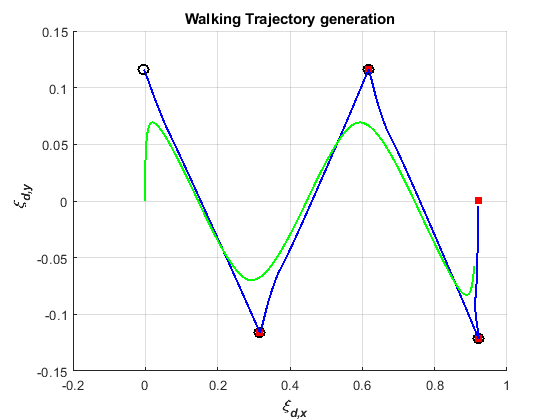

figure
% scatter3(r_vrp(:,1), r_vrp(:,2), r_vrp(:,3),50,'c','d',"filled")
hold on
scatter3(xi_ini(:,1), xi_ini(:,2), xi_ini(:,3),60,'o','MarkerEdgeColor','k','LineWidth',1.5)
scatter3(xi_eos(:,1), xi_eos(:,2), xi_eos(:,3),50,'r','s',"filled")

plot3(xi_d_mod(:,1), xi_d_mod(:,2), xi_d_mod(:,3),'b','LineWidth', 1.5)

% scatter3(xi_iniDS(2:end,1), xi_iniDS(2:end,2), xi_iniDS(2:end,3),50,'m','*')
% scatter3(xi_eoDS(:,1), xi_eoDS(:,2), xi_eoDS(:,3),50,[.8 .3 .09],'*')

plot3(x_com(:,1), x_com(:,2), x_com(:,3),'g','LineWidth', 1.5)

xlabel('\bf \it \xi_{d,x}')
ylabel('\bf \it \xi_{d,y}')
zlabel('\bf \it \xi_{d,z}')
title('Walking Trajectory generation')
grid on

#### `plot`

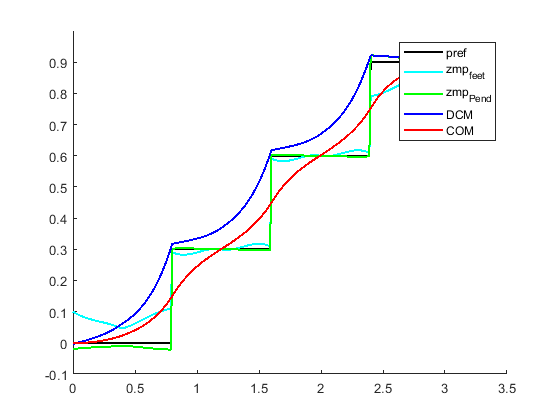

figure
hold on
plot(t,p_ref(:,1),'k','LineWidth', 1.5)
% plot(t,swing_traj(:,1),'m','LineWidth', 1.5)
plot(t,zmp_feet(:,1),'c','LineWidth', 1.5)
plot(t,zmp_pend(:,1),'g','LineWidth', 1.5)
plot(t,xi_d_mod(:,1),'b','LineWidth', 1.5)
plot(t,x_com(:,1),'r','LineWidth', 1.5)
ylim([-0.1 1])
legend('pref','zmp_{feet}','zmp_{Pend}','DCM','COM')

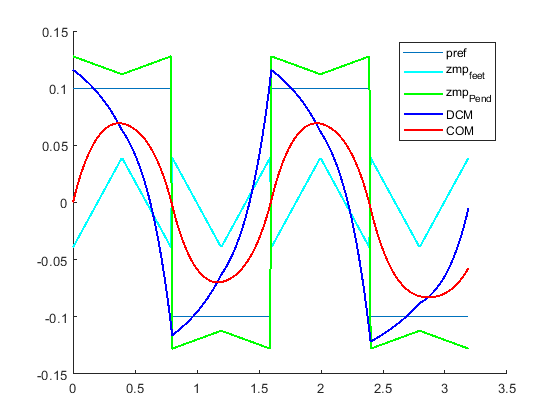

figure
hold on
plot(t,p_ref(:,2))
% plot(t,swing_traj(:,2),'m','LineWidth', 1.5)
plot(t,zmp_feet(:,2),'c','LineWidth', 1.5)
plot(t,zmp_pend(:,2),'g','LineWidth', 1.5)
plot(t,xi_d_mod(:,2),'b','LineWidth', 1.5)
plot(t,x_com(:,2),'r','LineWidth', 1.5)
legend('pref','zmp_{feet}','zmp_{Pend}','DCM','COM')

#### `functions definition`

function [xi_ini, xi_eos] = Xi(N, zmp_pend, omega, t_step, t_sample, r_vrp)
xi_eos = zeros(N+2,3);
xi_eos(N+2,:) = [zmp_pend(end,1) r_vrp(end,2) zmp_pend(end,3)];
for i = N+1:-1:1
    xi_eos(i,:) = zmp_pend(i*int32(t_step/t_sample)+1,:) + (exp(-omega*t_step))*(xi_eos(i+1,:)-zmp_pend(i*int32(t_step/t_sample)+1,:));
    xi_ini(i+1,:) = xi_eos(i,:);
end
xi_ini(1,:) = zmp_pend(i*int32(t_step/t_sample),:) + (exp(-omega*t_step))*(xi_eos(i,:)-zmp_pend(i*int32(t_step/t_sample),:));
end


function [xi_iniDS, xi_dot_iniDS, xi_eoDS, xi_dot_eoDS] = Xi_DS(N, r_vrp, xi_ini, xi_eos, omega, t_step, tDS, alpha)
for i = 1:N+2
    xi_eoDS(i,:) = r_vrp(i,:) + exp(omega*((1-alpha)*tDS))*(xi_ini(i,:) - r_vrp(i,:));
    xi_dot_eoDS(i,:) = omega*exp(omega*((1-alpha)*tDS))*(xi_ini(i,:) - r_vrp(i,:));
    if i == 1
        xi_iniDS(i,:) = r_vrp(i,:) + exp(-omega*t_step)*(xi_eos(i,:) - r_vrp(i,:));    
        xi_dot_iniDS(i,:) = omega*exp(-omega*(t_step))*(xi_eos(i,:) - r_vrp(i,:));
    else
        xi_iniDS(i,:) = r_vrp(i-1,:) + exp(-omega*(alpha*tDS))*(xi_ini(i,:) - r_vrp(i-1,:));    
        xi_dot_iniDS(i,:) = omega*exp(-omega*(alpha*tDS))*(xi_ini(i,:) - r_vrp(i-1,:));
    end
end
end